## Steering Model

Loading data

clear, clc
data = csvread("data_steering.csv",1,0);

time = data(:,1)/1000;
voltage = data(:,2);
position = data(:,3);
Ts = mean(diff(time))

Ts = 0.0100

Filtering speed mesured

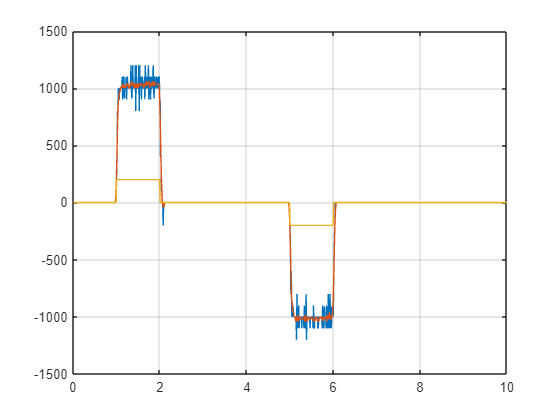

speed_raw = diff(position)./diff(time);

speed = movmean(speed_raw,5);

hold off

plot(time(1:end-1), speed_raw,time(1:end-1), speed)
hold on 
plot(time, 40*voltage)

grid on
hold off

Model estimation

DCData = iddata(speed,voltage(1:end-1),Ts);
get(DCData);

ans = struct with fields:
              Domain: 'Time'
                Name: ''
          OutputData: [995×1 double]
                   y: 'Same as OutputData'
          OutputName: {'y1'}
          OutputUnit: {''}
           InputData: [995×1 double]
                   u: 'Same as InputData'
           InputName: {'u1'}
           InputUnit: {''}
              Period: Inf
         InterSample: 'zoh'
                  Ts: 0.0100
              Tstart: 0.0100
    SamplingInstants: [995×1 double]
            TimeUnit: 'seconds'
      ExperimentName: 'Exp1'
               Notes: {}
            UserData: []


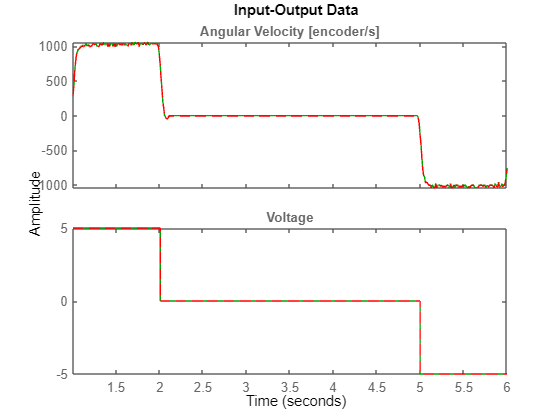

DCData.InputName = 'Voltage';
DCData.OutputName = 'Angular Velocity [encoder/s]';
DCData.TimeUnit = 'seconds';
DCData.InputUnit = 'V';
DCData.OutputUnit = 'encoder/s';
% Select time window for data used for estimation and model parameter validation
twin_init=1;
twin_fin=6;
pas=time(length(speed))/length(speed);
NEstimStart=round(twin_init/pas);
NEstimEnd=round(twin_fin/pas);
NValStart=1;
NValEnd=length(speed);
% select data for identif
DCDataIdent = DCData(NEstimStart:NEstimEnd);
% plot raw data for identif
figure(2)
plot(DCDataIdent,'-g');
hold on
% plot data after having removed the trend (mean)
DCDataIdent = detrend(DCDataIdent);
plot(DCDataIdent,'--r');
hold off


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Estimate models parameters  %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% transfert function parameter estimation
TFModel = tfest(DCDataIdent, 1, 0, 0)       % first order + integrator

TFModel =
  From input "Voltage" to output "Angular Velocity [encoder/s]":
    9925
  ---------
  s + 48.96
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                 
Estimated using TFEST on time domain data "DCDataIdent".
Fit to estimation data: 95.32%                          
FPE: 897.8, MSE: 887                                    
 
Model Properties


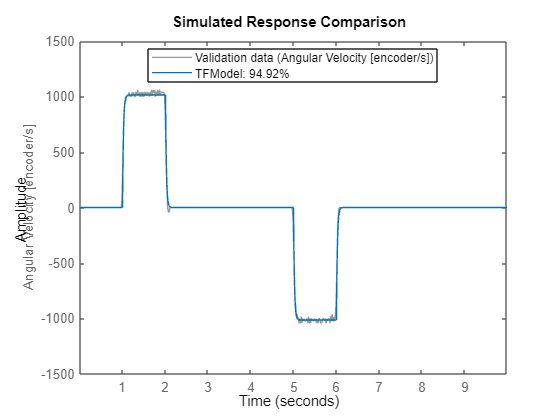

%Validating the Estimated Model to Experimental Output
DCDataVal = DCData(NValStart:NValEnd);      % select an independent data set for validation
DCDataVal = detrend(DCDataVal);             % preprocess the validation data
figure(3)
set(gcf,'DefaultLegendLocation','best')
compare(DCDataVal,TFModel);

PID Tuning for Control in Position [pos in number of encoders ]

K = TFModel.Numerator/TFModel.Denominator(2)

K = 202.7269

tau = 1/TFModel.Denominator(2)

tau = 0.0204


sys = tf([K],[tau 1 0])

sys =
 
       202.7
  ---------------
  0.02042 s^2 + s
 
Continuous-time transfer function.



sys_d = c2d(sys, Ts)

sys_d =
 
    0.4274 z + 0.3629
  ----------------------
  z^2 - 1.612 z + 0.6117
 
Sample time: 0.010039 seconds
Discrete-time transfer function.




pidTuner(sys_d)% z =0.7, tr = 0.1s
Kp	= 0.084374

Kp = 0.0844

Ki	= 0.029581

Ki = 0.0296

After the experiment, with find this coeficient to covert the encoder data to rad

D = [deg2rad(37)/1250, deg2rad(28)/1000, deg2rad(22.5)/750, deg2rad(16)/500, deg2rad(7.5)/250]

D = 1.0e-03 *

    0.5166    0.4887    0.5236    0.5585    0.5236


mean(D)

ans = 5.2220e-04

std(D)

ans = 2.4879e-05

100.0*std(D)/mean(D)

ans = 4.7643

coef = 5.2e-4

coef = 5.2000e-04

PID Tuning for Control in Position [pos in rad]

K = coef*TFModel.Numerator/TFModel.Denominator(2)

K = 0.1054

tau = 1/TFModel.Denominator(2)

tau = 0.0204

sys = tf([K],[tau 1 0])

sys =
 
      0.1054
  ---------------
  0.02042 s^2 + s
 
Continuous-time transfer function.



sys_d = c2d(sys, Ts)

sys_d =
 
  0.0002222 z + 0.0001887
  -----------------------
  z^2 - 1.612 z + 0.6117
 
Sample time: 0.010039 seconds
Discrete-time transfer function.




pidTuner(sys_d)% z =0.7, tr = 0.1s
Kp	= 205.6;
Ki	= 72.09;

Ki = 203.1000

Finding Luenbergue coeficients for speed estimation

%x = v theta d
%y = theta
Ao = [-1/tau, 0 K/tau; 1 0 0; 0 0 0];
Bo = [K/tau; 0; 0];
Co = [0 1 0];


Ao = [-1/tau, 0; 1 0];
Bo = [K/tau; 0];
Co = [0 1];

sys = ss(Ao,Bo,Co,0)

sys =
 
  A = 
           x1      x2
   x1  -48.96       0
   x2       1       0
 
  B = 
          u1
   x1  5.161
   x2      0
 
  C = 
       x1  x2
   y1   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.




sys_d = c2d(sys,Ts, 'zoh')

sys_d =
 
  A = 
             x1        x2
   x1    0.6117         0
   x2  0.007931         1
 
  B = 
              u1
   x1    0.04093
   x2  0.0002222
 
  C = 
       x1  x2
   y1   0   1
 
  D = 
       u1
   y1   0
 
Sample time: 0.010039 seconds
Discrete-time state-space model.



rank(obsv(sys_d))

ans = 2


Aod = sys_d.A;
Bod = sys_d.B;
Cod = sys_d.C;
Dod = sys_d.D;

vp = [-10/tau, -20/tau, -30/tau]

vp = 1.0e+03 *

   -0.4896   -0.9792   -1.4688


vp = [-10/tau, -20/tau]

vp =  -489.5970 -979.1939


Ko = place(Ao', Co', vp)'

Ko = 1.0e+05 *

    4.0990
    0.0142


Kod = place(Aod', Cod', exp(vp*Ts))'

Kod =    46.6087
    1.6043


## Linear Model

Loading data

clear, clc
data = csvread("data_linear.csv",1,0);

time = data(:,1)/1000;
voltage = data(:,2);
position = data(:,3);
Ts = mean(diff(time))

Ts = 0.0100

Filtering speed mesured

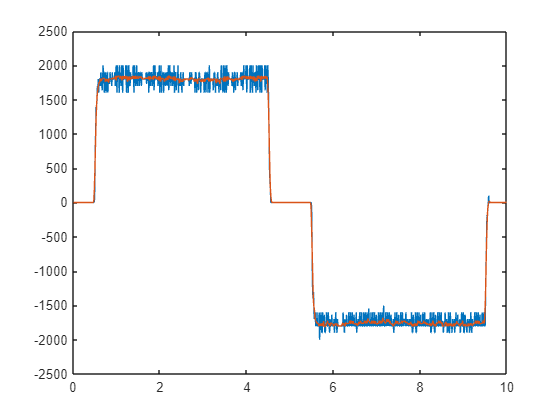

speed_raw = diff(position)./diff(time);

speed = movmean(speed_raw,5);

hold off

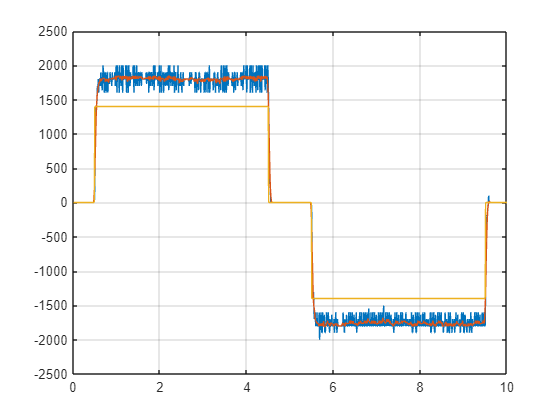

plot(time(1:end-1), speed_raw,time(1:end-1), speed)
hold on 
plot(time, 200*voltage)

grid on
hold off

Model estimation

DCData = iddata(speed,voltage(1:end-1),Ts);
get(DCData);

ans = struct with fields:
              Domain: 'Time'
                Name: ''
          OutputData: [995×1 double]
                   y: 'Same as OutputData'
          OutputName: {'y1'}
          OutputUnit: {''}
           InputData: [995×1 double]
                   u: 'Same as InputData'
           InputName: {'u1'}
           InputUnit: {''}
              Period: Inf
         InterSample: 'zoh'
                  Ts: 0.0100
              Tstart: 0.0100
    SamplingInstants: [995×1 double]
            TimeUnit: 'seconds'
      ExperimentName: 'Exp1'
               Notes: {}
            UserData: []


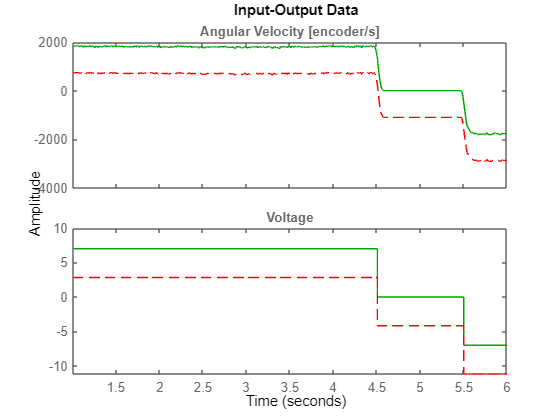

DCData.InputName = 'Voltage';
DCData.OutputName = 'Angular Velocity [encoder/s]';
DCData.TimeUnit = 'seconds';
DCData.InputUnit = 'V';
DCData.OutputUnit = 'encoder/s';
% Select time window for data used for estimation and model parameter validation
twin_init=1;
twin_fin=6;
pas=time(length(speed))/length(speed);
NEstimStart=round(twin_init/pas);
NEstimEnd=round(twin_fin/pas);
NValStart=1;
NValEnd=length(speed);
% select data for identif
DCDataIdent = DCData(NEstimStart:NEstimEnd);
% plot raw data for identif
figure(2)
plot(DCDataIdent,'-g');
hold on
% plot data after having removed the trend (mean)
DCDataIdent = detrend(DCDataIdent);
plot(DCDataIdent,'--r');
hold off


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Estimate models parameters  %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% transfert function parameter estimation
TFModel = tfest(DCDataIdent, 1, 0, 0)       % first order + integrator

TFModel =
  From input "Voltage" to output "Angular Velocity [encoder/s]":
  1.287e04
  ---------
  s + 50.29
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                 
Estimated using TFEST on time domain data "DCDataIdent".
Fit to estimation data: 96.05%                          
FPE: 2177, MSE: 2151                                    
 
Model Properties


%Validating the Estimated Model to Experimental Output
DCDataVal = DCData(NValStart:NValEnd);      % select an independent data set for validation
DCDataVal = detrend(DCDataVal);             % preprocess the validation data
figure(3)
set(gcf,'DefaultLegendLocation','best')
compare(DCDataVal,TFModel);

PID Tuning for Control in Position [pos in number of encoders ]

K = TFModel.Numerator/TFModel.Denominator(2)

K = 255.9347

tau = 1/TFModel.Denominator(2)

tau = 0.0199


sys = tf([K],[tau 1 0])

sys =
 
       255.9
  ---------------
  0.01988 s^2 + s
 
Continuous-time transfer function.



sys_d = c2d(sys, Ts)

sys_d =
 
     0.552 z + 0.4666
  ----------------------
  z^2 - 1.604 z + 0.6036
 
Sample time: 0.010039 seconds
Discrete-time transfer function.




pidTuner(sys_d)% z =0.85, tr = 3.0s
Kp = 0.038753
Ki = 0.074189



After the experiment, with find this coeficient to covert the encoder data to rad

D = [0.761/20000, 0.767/20000, 0.765/20000;
     0.380/10000, 0.380/10000, 0.378/10000;
     0.574/15000, 0.573/15000, 0.574/15000;
     0.192/5000, 0.190/5000, 0.195/5000;
     0.254/6667, 0.255/6667, 0.254/6667;
     0.511/13333, 0.510/13333, 0.510/13333;
     1.021/26667, 1.019/26667, 1.019/26667;]'

D = 1.0e-04 *

    0.3805    0.3800    0.3827    0.3840    0.3810    0.3833    0.3829
    0.3835    0.3800    0.3820    0.3800    0.3825    0.3825    0.3821
    0.3825    0.3780    0.3827    0.3900    0.3810    0.3825    0.3821



mean(D)

ans = 1.0e-04 *

    0.3822    0.3793    0.3824    0.3847    0.3815    0.3828    0.3824


std(D)

ans = 1.0e-06 *

    0.1528    0.1155    0.0385    0.5033    0.0866    0.0433    0.0433


100.*std(D)./mean(D)

ans =     0.3997    0.3044    0.1006    1.3085    0.2270    0.1131    0.1132



mean(mean(D))

ans = 3.8217e-05

std(mean(D))

ans = 1.5926e-07

100.0*std(mean(D))./mean(mean(D))

ans = 0.4167

coef = 3.82e-5

coef = 3.8200e-05

PID Tuning for Control in Speed [spd in m/s]

K = coef*TFModel.Numerator/TFModel.Denominator(2)

K = 0.0098

tau = 1/TFModel.Denominator(2)

tau = 0.0199


sys = tf([K],[tau 1])

sys =
 
    0.009777
  -------------
  0.01988 s + 1
 
Continuous-time transfer function.



sys_d = c2d(sys, Ts)

sys_d =
 
   0.003876
  ----------
  z - 0.6036
 
Sample time: 0.010039 seconds
Discrete-time transfer function.




%pidTuner(sys_d)% z =0.7, tr = 0.5s

Kp = 26.11;
Ki = 2184.2232;
Ti = Kp/Ki

Ti = 0.0120


Kc = 1/sqrt(Ti)

Kc = 9.1463

Finding Luenbergue coeficients for speed estimation

%x = v theta d
%y = theta
Ao = [-1/tau, 0 K/tau; 1 0 0; 0 0 0];
Bo = [K/tau; 0; 0];
Co = [0 1 0];


Ao = [-1/tau, 0; 1 0];
Bo = [K/tau; 0];
Co = [0 1];

sys = ss(Ao,Bo,Co,0)

sys =
 
  A = 
           x1      x2
   x1  -50.29       0
   x2       1       0
 
  B = 
           u1
   x1  0.4917
   x2       0
 
  C = 
       x1  x2
   y1   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.




sys_d = c2d(sys,Ts, 'zoh')

sys_d =
 
  A = 
             x1        x2
   x1    0.6036         0
   x2  0.007883         1
 
  B = 
              u1
   x1   0.003876
   x2  2.109e-05
 
  C = 
       x1  x2
   y1   0   1
 
  D = 
       u1
   y1   0
 
Sample time: 0.010039 seconds
Discrete-time state-space model.



rank(obsv(sys_d))

ans = 2


Aod = sys_d.A;
Bod = sys_d.B;
Cod = sys_d.C;
Dod = sys_d.D;

vp = [-10/tau, -20/tau, -30/tau]

vp = 1.0e+03 *

   -0.5029   -1.0059   -1.5088


vp = [-10/tau, -20/tau]

vp = 1.0e+03 *

   -0.5029   -1.0059


Ko = place(Ao', Co', vp)'

Ko = 1.0e+05 *

    4.3253
    0.0146


Kod = place(Aod', Cod', exp(vp*Ts))'

Kod =    45.7207
    1.5971
